n = 100:5000;

[Fmid] = leftsolver(n);
[Ftrap] = trapsolver(n);

sprintf('%.2f',Ftrap(4901))

ans = '1480.57'

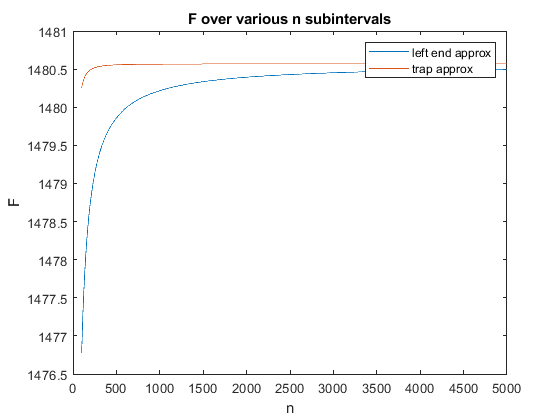


figure

plot(n,Fmid)
hold on
plot(n,Ftrap)
xlabel('n')
ylabel('F')
title('F over various n subintervals')
legend('left end approx','trap approx')


%True value of F is 1480.57

function [Fmid] = leftsolver(n)
   Fmid = ones(1,5000-100);
   for i = n
       dz= 30/i;
       z = 0:dz:30-dz;
       func = 200*exp(-z/15).*z./(z+5);
       approx = dz*sum(func);
       Fmid(i-99) = approx;
   end
end

function [Ftrap] = trapsolver(n)
   Ftrap = ones(1,5000-100);
   for i = n
       dz= 30/i;
       z = dz:dz:30;
       func_xi = 200*exp(-z/15).*z./(z+5);
       func_ximinus = 200*exp(-(z-dz)/15).*(z-dz)./(z-dz+5);
       approx = dz/2*sum(func_xi+func_ximinus);
       Ftrap(i-99) = approx;
   end
end